## Nonlinear System Midterm Exam

電機碩一 陳昕佑 61375017H

    I designed a third-order nonlinear system inspired by “single-joint manipulator + integral action” ideas, and its construction guarantees local asymptotic stability about the origin. It features:

- A linear part chosen to be asymptotically stable at the origin.

- Six distinct nonlinear terms, all of which vanish at $\left(0,0,0\right)$.

- A total of three states $\left(x_1 ,x_2 ,x_3 \right)$, making it third-order.

**Porposed System**

Define the states:

- $x_1 :$as the joint angle error $q-q_{\textrm{desired}}$.

- $x_2 :$the joint angular velocity (or rate of change of $x_1$).

- $x_3 :$an integral-of-error state, often introduced in control to remove steady-state offset.

The dynamics are:

$\dot{x_1 } =x_2$, 

$\dot{x_2 } =-2x_1 -3x_2 -4x_3 +x_1^2 x_2 +x_1^3 +\sin \left(x_1 \right)+x_2^2 x_3 +x_1^2 \sin \left(x_3 \right)+x_1 x_2 x_3$, 

$\dot{x_3 } =x_1$, 

counting the six nonlinear terms, all appear in the $\dot{x_2 }$ equation, and each of these is zero at $\left(x_1 ,x_2 ,x_3 \right)=\left(0,0,0\right)$.

(1) Find the equilibrium points of the system.

function dx = my_system(x)
    % x = [x1; x2; x3]
    x1 = x(1);
    x2 = x(2);
    x3 = x(3);

    dx1 = x2;
    dx2 = -2*x1 - 3*x2 - 4*x3 ...
          + x1^2 * x2 ...
          + x1^3 ...
          + sin(x1) ...
          + x2^2 * x3 ...
          + x1^2 * sin(x3) ...
          + x1 * x2 * x3;
    dx3 = x1;

    dx = [dx1; dx2; dx3];
end

% Initial guess near origin
x0 = [0; 0; 0];

% Solve for equilibrium point (dx = 0)
equilibrium = fsolve(@my_system, x0);

disp('Equilibrium point:');
disp(equilibrium);

x0_list = [0 0 0; 1 1 1; -1 -1 -1; 0.5 -0.5 0.5];
for i = 1:size(x0_list, 1)
    x0 = x0_list(i, :)';
    eq = fsolve(@my_system, x0);
    disp(['Guess ' num2str(i) ': ' mat2str(eq)]);
end

(2) Linearize the system around the equilibrium points.

syms x1 x2 x3

dx1 = x2;


Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


dx2 = -2*x1 - 3*x2 - 4*x3 ...
      + x1^2 * x2 ...

Equilibrium point:


      + x1^3 ...

     0
     0
     0



      + sin(x1) ...
      + x2^2 * x3 ...
      + x1^2 * sin(x3) ...
      + x1 * x2 * x3;
dx3 = x1;

f = [dx1; dx2; dx3];


Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Guess 1: [0;0;0]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Guess 2: [0;0;0]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Guess 3: [0;0;0]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Guess 4: [0;9.25185853854298e-18;-6.93889390390723e-18]


x = [x1; x2; x3];

J = jacobian(f, x);

J_eq = double(subs(J, x, [0; 0; 0]));
disp('Jacobian at the origin:');
disp(J_eq);
eig(J)  % Get eigenvalues

(5) Plot a Lyapunov function using MATLAB

% System matrix
A = [0 1 0;
 -2 -3 -4;
 1 0 0];
% Solve Lyapunov equation: A'P + P*A = -Q
Q = eye(3);
P = lyap(A', Q);
% Generate grid over x1 and x2 (fix x3 = 0)
[x1, x2] = meshgrid(linspace(-2, 2, 100), linspace(-2, 2, 100));
x3 = 0;
V = zeros(size(x1));
for i = 1:numel(x1)

Jacobian at the origin:


 x_vec = [x1(i); x2(i); x3];

     0     1     0
    -1    -3    -4
     1     0     0



 V(i) = x_vec' * P * x_vec;

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{x_{1}\,x_{3}}{3}+\sigma_{1}+\frac{\sigma_{4}}{\sigma_{3}}+\sigma_{3}+\frac{{x_{1}}^{2}}{3}-1\\ \frac{x_{1}\,x_{3}}{3}+\sigma_{1}-\frac{\sigma_{4}}{2\,\sigma_{3}}-\frac{\sigma_{3}}{2}+\frac{{x_{1}}^{2}}{3}-1-\sigma_{2}\\ \frac{x_{1}\,x_{3}}{3}+\sigma_{1}-\frac{\sigma_{4}}{2\,\sigma_{3}}-\frac{\sigma_{3}}{2}+\frac{{x_{1}}^{2}}{3}-1+\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,x_{2}\,x_{3}}{3}\\ \sigma_{2}=\frac{\sqrt{3}\,\left(\frac{\sigma_{4}}{\sigma_{3}}-\sigma_{3}\right)\,\mathrm{i}}{2}\\ \sigma_{3}={\left(\sigma_{5}+\frac{{x_{1}}^{2}\,\cos\left(x_{3}\right)}{2}+\frac{{\sigma_{6}}^{3}}{27}+\frac{x_{1}\,x_{2}}{2}+\frac{{x_{2}}^{2}}{2}+\sqrt{{\left(\sigma_{5}+\frac{{x_{1}}^{2}\,\cos\left(x_{3}\right)}{2}+\frac{{\sigma_{6}}^{3}}{27}+\frac{x_{1}\,x_{2}}{2}+\frac{{x_{2}}^{2}}{2}-2\right)}^{2}-{\sigma_{4}}^{3}}-2\right)}^{1/3}\\ \sigma_{4}=\frac{\cos\left(x_{1}\right)}{3}+\frac{{\sigma_{6}}^{2}}{9}+\frac{2\,x_{1}\,x_{2}}{3}+\frac{x_{2}\,x_{3}}{3}+\frac{2\,x_{1}\,\sin\left(x_{3}\right)}{3}+{x_{1}}^{2}-\frac{2}{3}\\ \sigma_{5}=\frac{\sigma_{6}\,\left(\cos\left(x_{1}\right)+2\,x_{1}\,x_{2}+x_{2}\,x_{3}+2\,x_{1}\,\sin\left(x_{3}\right)+3\,{x_{1}}^{2}-2\right)}{6}\\ \sigma_{6}={x_{1}}^{2}+x_{3}\,x_{1}+2\,x_{2}\,x_{3}-3 \end{array}$$

end
% Plot Lyapunov function
figure;
surf(x1, x2, V, 'EdgeColor', 'none');
xlabel('x_1'); ylabel('x_2'); zlabel('V(x)');
title('Lyapunov Function V(x) over x_1-x_2 Plane (x_3 = 0)');
colormap jet; colorbar;
view(30, 40); % 3D view angle

% Optional: Contour plot
figure;
contourf(x1, x2, V, 30);
xlabel('x_1'); ylabel('x_2');
title('Contour of V(x) (x_3 = 0)');
colorbar;

(6) Plot state trajectories of the system with Lyapunov function near the origin using MATLAB.

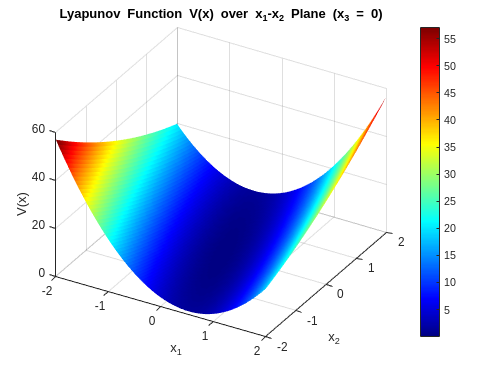

% System definition: nonlinear system
function dx = nonlinear_sys(t, x)
 x1 = x(1); x2 = x(2); x3 = x(3);
 dx1 = x2;
 dx2 = -2*x1 - 3*x2 - 4*x3 ...
 + x1^2 * x2 + x1^3 + sin(x1) ...
 + x2^2 * x3 + x1^2 * sin(x3) + x1 * x2 * x3;
 dx3 = x1;
 dx = [dx1; dx2; dx3];

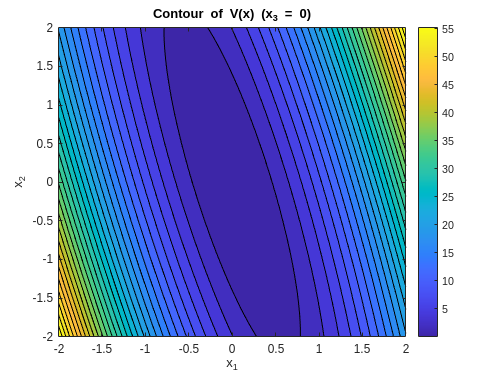

end
% Solve Lyapunov equation for V(x) = x' P x
A = [0 1 0;
 -2 -3 -4;
 1 0 0];
Q = eye(3);
P = lyap(A', Q);

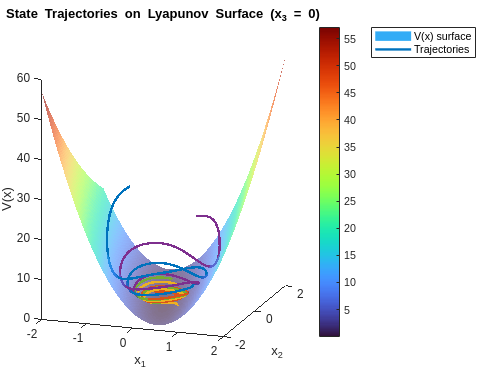

% Grid for V(x1, x2), fix x3 = 0
[x1g, x2g] = meshgrid(linspace(-2,2,100), linspace(-2,2,100));
x3 = 0;
V = zeros(size(x1g));
for i = 1:numel(x1g)
 x = [x1g(i); x2g(i); x3];
 V(i) = x' * P * x;
end
% Simulate trajectories from different initial points near origin
init_conditions = [
 0.5 0.5 0;
 -0.5 0.5 0;
 0.5 -0.5 0;
 -0.5 -0.5 0;
 0.3 0.3 0
];
tspan = [0 10];
figure;
hold on;
surf(x1g, x2g, V, 'EdgeColor', 'none', 'FaceAlpha', 0.6);
xlabel('x_1'); ylabel('x_2'); zlabel('V(x)');
title('State Trajectories on Lyapunov Surface (x_3 = 0)');
colormap turbo;
colorbar;
view(30,40);
for i = 1:size(init_conditions,1)
 [t, x] = ode45(@nonlinear_sys, tspan, init_conditions(i,:)');

 % Project to x1-x2 plane at x3 = 0
 V_traj = zeros(length(t),1);
 for k = 1:length(t)
 xk = x(k,:)';
 V_traj(k) = xk' * P * xk;
 end

 plot3(x(:,1), x(:,2), V_traj, 'LineWidth', 2);
end
legend('V(x) surface','Trajectories');